Exercise 4:

In htis task we investigate two methods of design of a feedback control system. Firstly we will utilize Matlab's Control System Designer GUI, then we will apply Ziegler-Nichols method for the same system, and finally we will compare the results, as well as ease of use of each method.

1) Defining the system and time domain specifications:

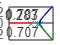

%defining the system of interest

K=8;               %gain
Z=[];              %zeros
P=[-0.01,-0.2,-1]; %poles
sys=zpk(Z,P,K);    %transfer funtion

%defining system specifications:


zeta=0.707;        %damping ratio of dominant close-loop poles
wn=0.2829;         %natural frequency of dominant close-loop poles

%plotting the rlocus plot of the system, and generating a grid of constant
%damping factors and natural frequencies

rlocus(sys)
sgrid(zeta,wn)

2) The Root-Locus Design GUI (sisotool) tool of Matlab Control System Toolbox:

- Firsty we set up system specifications:

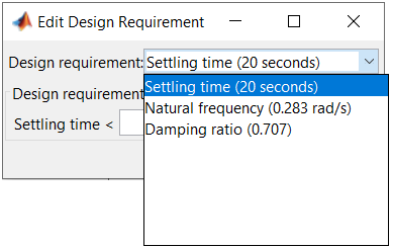

- Secondly we add a zero to the system to the right of the pole with the smallest magnitude. Adding zero allows us to shift the dominant poles to the left half-plane. 

- Finally we adjust the position of the poles such that they fit within the system specifictations. As a result we obtain the following locus plot:

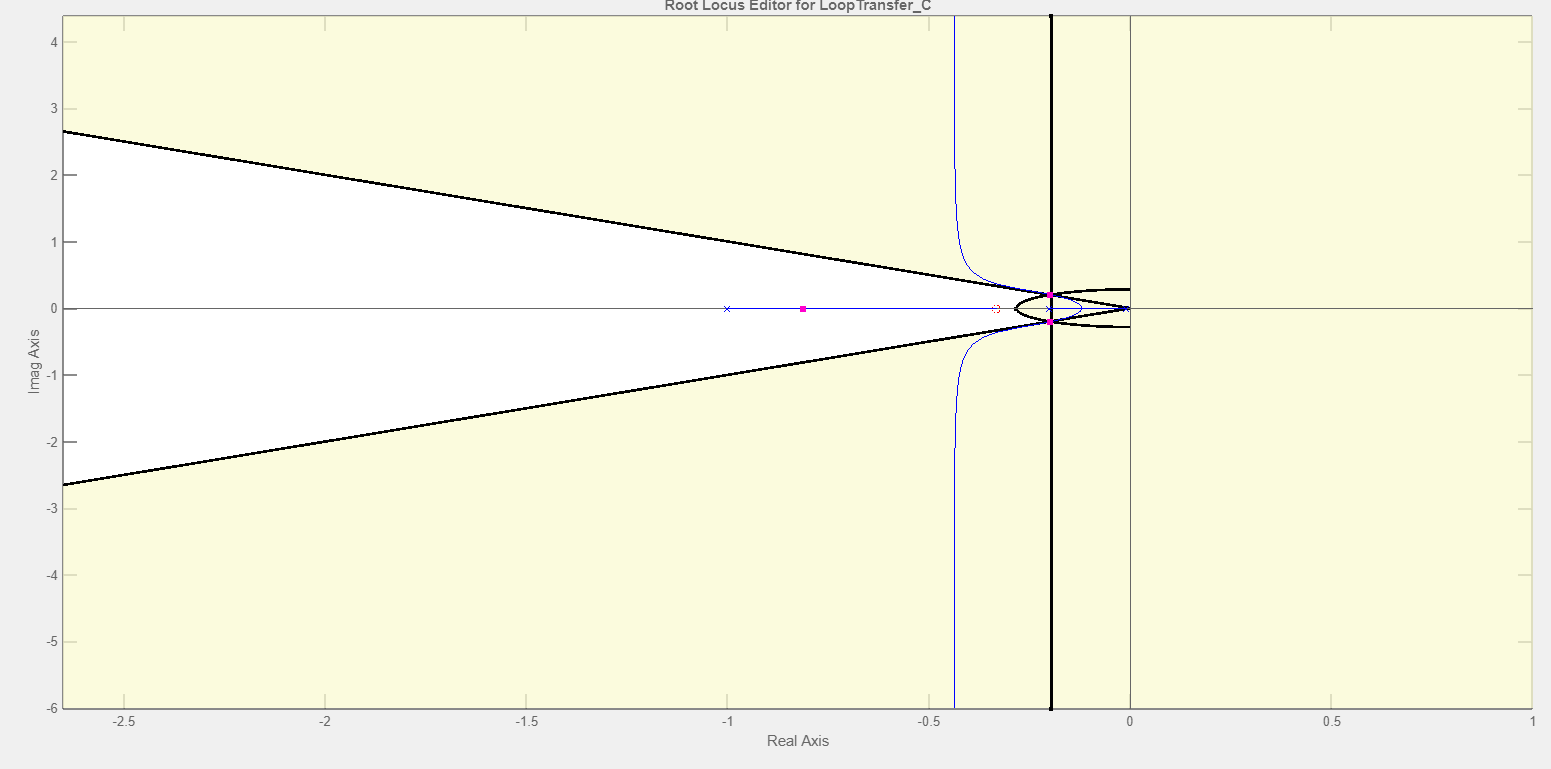

Based on the compensator data:

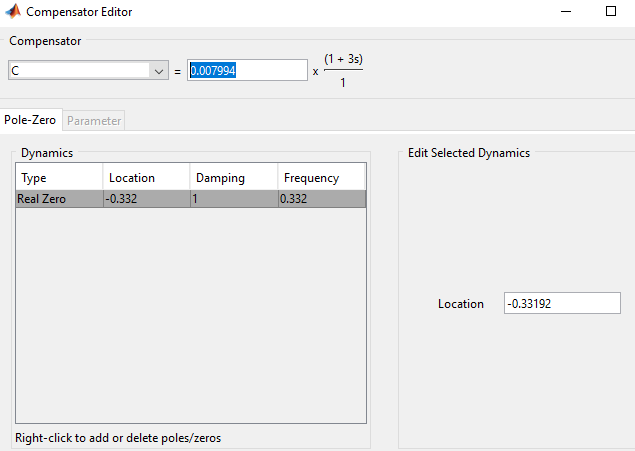

the PD controller is approximately 0.008 + 0.024s.

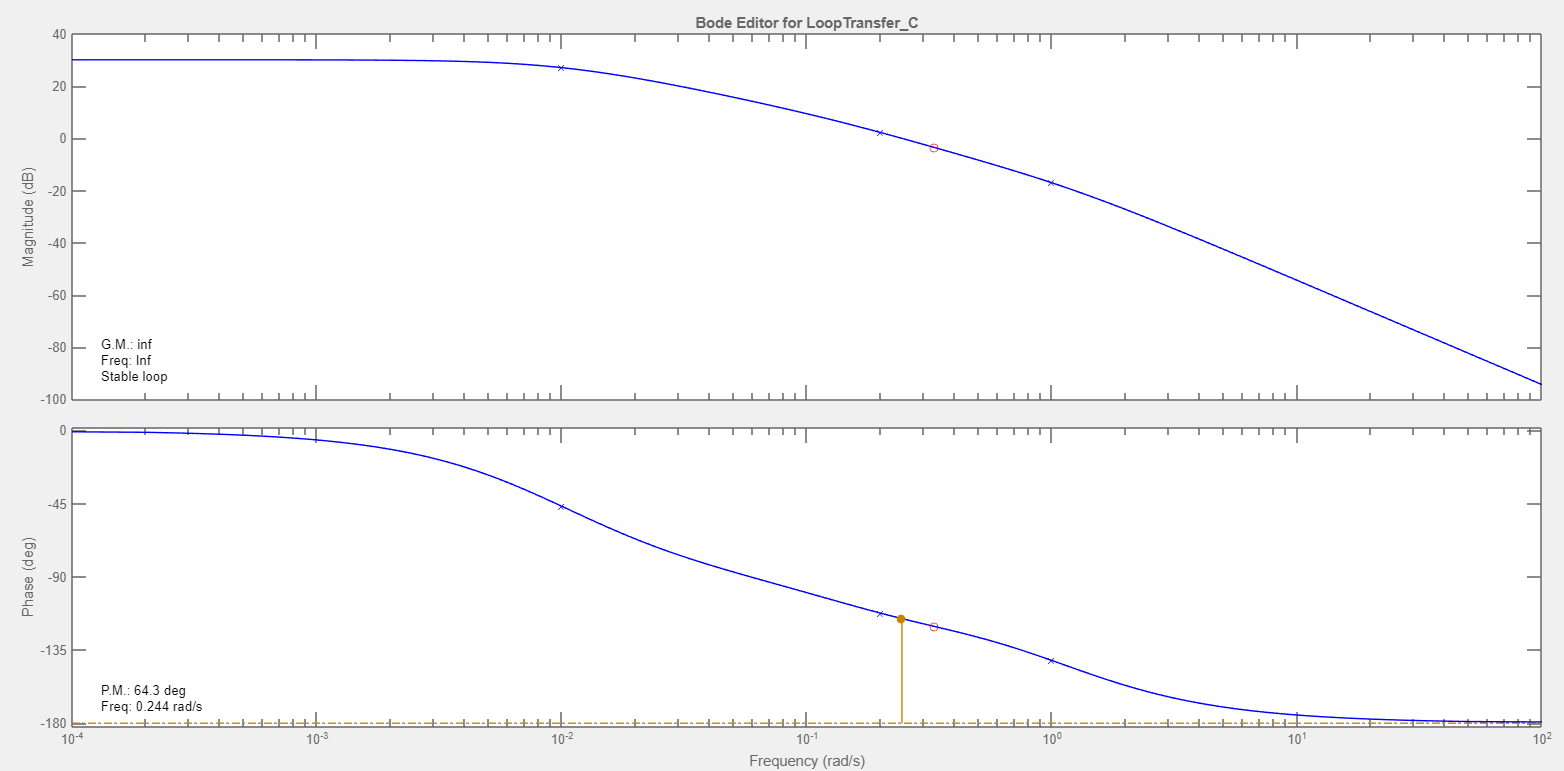

rys.4 Bode plot of the system

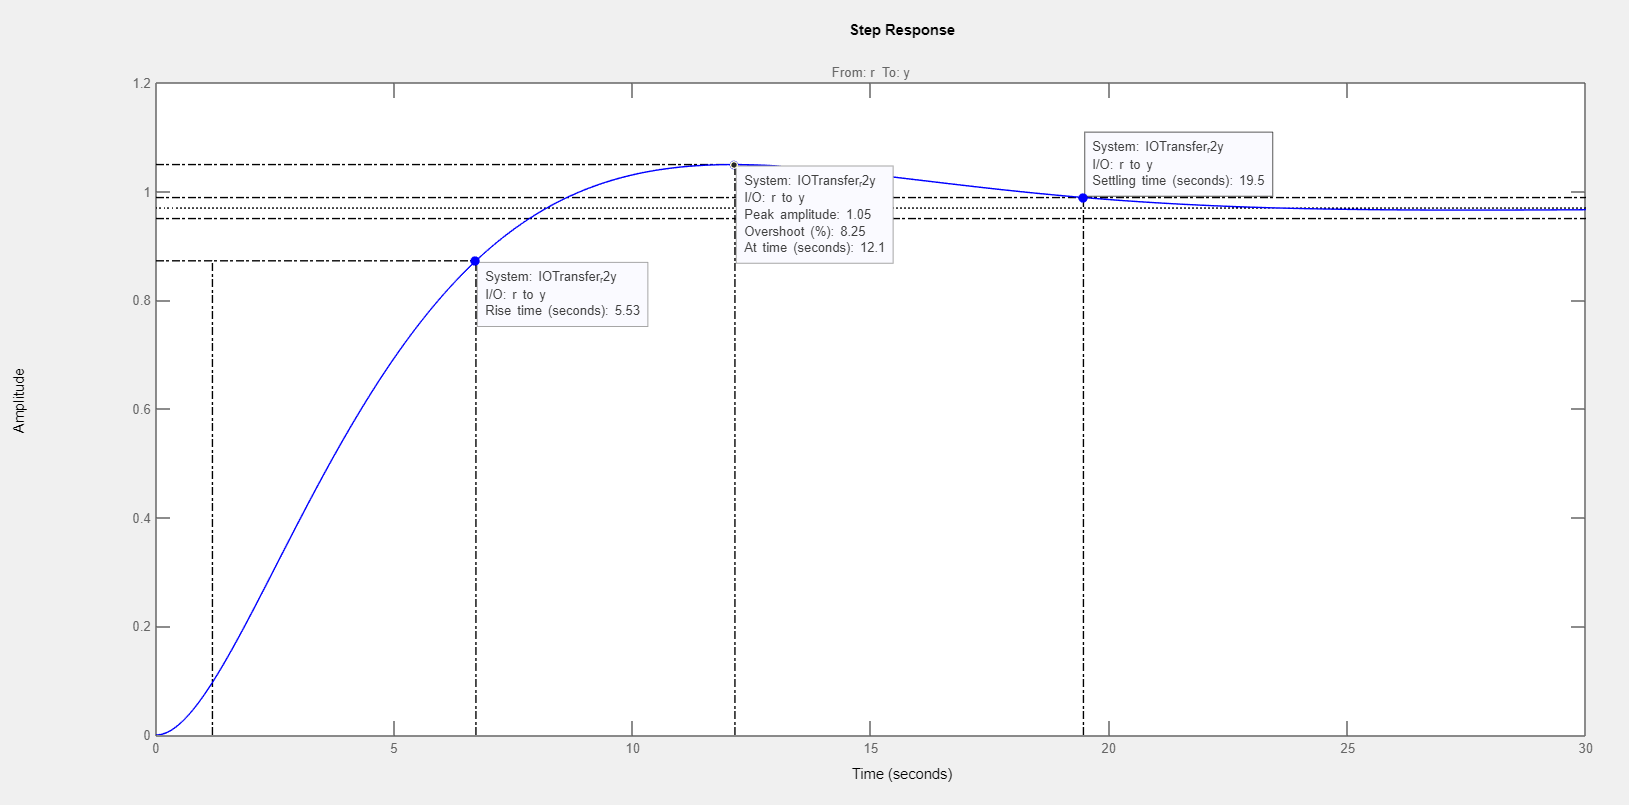

rys.5 Close-loop step response of the system

load('ControlSystemDesignerSession.mat')

controlSystemDesigner('ControlSystemDesignerSession.mat')

3) Ziegler-Nichols 

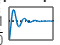

% open('Ex4sim.slx')
%From locusplot
Ku=0.0319; 
%From simulink
Tu=13.653;
K1=Ku/1.7;
Ti=Tu/2;
Td=Tu/8;
Ki=K1/Ti;
Kd=K1*Td;
W=pid(K1,Ki,Kd);
H=1;
Y=feedback(sys*W,H);
step(Y)